Clearance Function

clc;
clear;
l1=30; %Length of Link 1
l2=30; %Length of Link 2
l3=10;  %Length of Link 3
l4 =10; %Length of Link 4

%   DH  = [  a_n  alpha_n  d_n  theta_n]
DHparameter=[0 0 0.04 0;
             0.12 pi/2 0 13*pi/30;
             0.194 0 0 -23*pi/30;
             0 -pi/2 0.176 0;
             0 pi/2 0 pi/2;
             0 pi/2 0 0]

DHparameter =          0         0    0.0400         0
    0.1200    1.5708         0    1.3614
    0.1940         0         0   -2.4086
         0   -1.5708    0.1760         0
         0    1.5708         0    1.5708
         0    1.5708         0         0


## `Defining the asymmetric robot as a rigid tree`

%Defining a Robot Rigid Body Tree 
dental = rigidBodyTree("MaxNumBodies",6,"DataFormat","column");

%Setting the Gravity matrix w.r.t to the base frame of robot.
dental.Gravity = [0 0 -9.81];

%Creating links and joints
body1 = rigidBody('Body1');
joint1 = rigidBodyJoint('Joint1','revolute');
body1.Mass = 10;
body1.CenterOfMass = [0 0 0];
body2 = rigidBody('Body2');
joint2 = rigidBodyJoint('Joint2','revolute');
body2.Mass = 10;
body2.CenterOfMass = [0 0 0];
body3 = rigidBody('Body3');
joint3 = rigidBodyJoint('Joint3','revolute');
body3.Mass = 10;
joint3.PositionLimits = [-10 10]; %Position limit defines the maximum extension/retraction from mean position for a prismatic joint. 
body3.CenterOfMass = [0 0 0];
body4 = rigidBody('Body4');
joint4 = rigidBodyJoint('Joint4','revolute');
body4.Mass = 10;

body5 = rigidBody('Body5');
joint5 = rigidBodyJoint('Joint5','revolute');
body5.Mass = 10;

body6 = rigidBody('Body6');
joint6 = rigidBodyJoint('Joint6','revolute');
body6.Mass = 10;

%Settings the transformations to each joint with DH parameter.
%Assigning the joint of each link with the object 
setFixedTransform(joint1,DHparameter(1,:),"dh");
body1.Joint = joint1;
setFixedTransform(joint2,DHparameter(2,:),"dh");
body2.Joint = joint2;
setFixedTransform(joint3,DHparameter(3,:),"dh");
body3.Joint = joint3;
setFixedTransform(joint4,DHparameter(4,:),"dh");
body4.Joint = joint4;
setFixedTransform(joint5,DHparameter(5,:),"dh");
body5.Joint = joint5;
setFixedTransform(joint6,DHparameter(6,:),"dh");
body6.Joint = joint6;

addBody(dental,body1,'base');
addBody(dental,body2,'Body1');
addBody(dental,body3,'Body2');
addBody(dental,body4,'Body3');
addBody(dental,body5,'Body4');
addBody(dental,body6,'Body5');

showdetails(dental)

--------------------
Robot: (6 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1      revolute             base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  
   4        Body4        Joint4      revolute            Body3(3)   Body5(5)  
   5        Body5        Joint5      revolute            Body4(4)   Body6(6)  
   6        Body6        Joint6      revolute            Body5(5)   
--------------------



% show(dental);


**Point Cloud**

%Read in PCloud
stlData = stlread('1-3dm.stl');
points = stlData.Points;
ptCloud = pointCloud(points);

%Transformation (shrink and move)
Sx = 0.011;
Sy = 0.011;
Sz = 0.011;
tform = affine3d([Sx 0 0 0; 0 Sy 0 0; 0 0 Sz 0; 0 0 0 1]);
ptCloud = pctransform(ptCloud,tform);
rot = [1 0 0; 0 1 0; 0 0 1];
trans = [1.1 -0.35 -0.1];
tform = rigid3d(rot,trans);
ptCloud = pctransform(ptCloud,tform);

**Trajectory**

%Create Trajectory
startPose = trvec2tform([0.220641 -0.0406355 -0.0975])*axang2tform([1 0 0 pi]);
endPose = trvec2tform([0.26 -0.02 0])*axang2tform([1 0 0 pi]);

% Use a fixed random seed to ensure repeatable results
% rng(0);
ik = inverseKinematics("RigidBodyTree",dental);
weights = ones(1,6);
startConfig = ik("Body6",startPose,weights,dental.homeConfiguration);
endConfig = ik("Body6",endPose,weights,dental.homeConfiguration);
% startConfig = [0 0 0 0 0 0]';
% endConfig = [pi/2 0 0 0 0 0]';

% Show initial and final positions
% show(dental,startConfig);
% show(dental,endConfig);
t = 200;
q = trapveltraj([homeConfiguration(dental),startConfig,endConfig],t,"EndTime",2);

**Calling Functions**

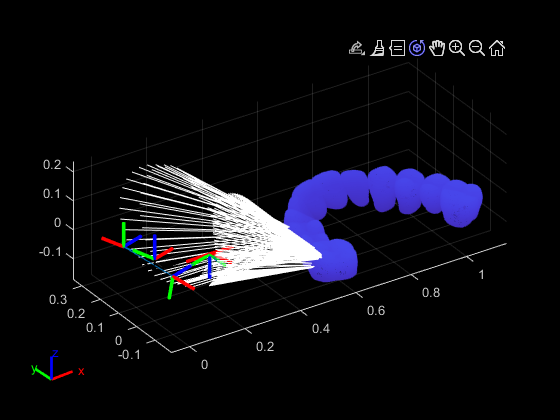

[minimum,ind,ee_arr] = min2pts(dental,q,t,ptCloud);
    
plotClosest(dental,q,t,ee_arr,ind,ptCloud);

**Closest Point Function:**

function [minimum,ind,ee_arr] = min2pts(bot,traj,time_array,ptCloud)
    hyp = zeros(length(ptCloud.Location(:,1)),length(time_array));
    ee_arr = zeros(time_array,3);
    
    for i = 1:1:time_array
        transform = getTransform(bot,traj(:,i),'Body6','base');
        ee = transform(1:3,4);
        ee_arr(i,:) = transpose(ee);
        d = abs(bsxfun(@minus, ee_arr(i,:), ptCloud.Location));
        hyp(:,i) = sqrt(d(:,1).^2 + d(:,2).^2 + d(:,3).^2); %Store hyp of each point at each frame
    end
    
    [minimum,ind] = min(hyp);
end

**Plot Distance between ee and closest point function:**

function [] = plotClosest(bot,traj,time_array,ee_arr,ind,ptCloud)
    fps = 15;
    r = rateControl(fps);
    set(gcf,'Visible','on')
    pcshow(ptCloud)
    hold on
    for i = 1:1:time_array
        show(bot,traj(:,i),'PreservePlot',false);
        drawnow
        waitfor(r);
        hold on
        line([ee_arr(i,1) ptCloud.Location(ind(i),1)],[ee_arr(i,2) ptCloud.Location(ind(i),2)],[ee_arr(i,3) ptCloud.Location(ind(i),3)],'Color','w')
    end
end